clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.82;-1.59;13.96];
u31=[0.0489;0.662;0.748];
r2=[-0.533;4.10;-0.01];
u32=[-0.598;-0.289;0.748];
r3=[7.60;8.81;8.23];
u33=[0.547;0.373;-0.750];
r4=[10.33;2.17;-5.74];
u34=[-0.596;0.287;-0.750];
r5=[14.71;7.86;22.20];
u35=[0.0494;-0.660;-0.750];
r6=[25.58;-1.59;13.96];
u36=[0.0489;0.662;0.748];
r7=[-7.06;-20.43;13.96];
u37=[0.0489;0.662;0.748];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

hold on
axis([0 15 0 20]);
for R3=1:0.5:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.7300    1.0000    1.0006


ans =    10.6300    1.5000    1.0001


ans =    10.4900    2.0000    1.0011


ans =    10.3300    2.5000    1.0005


ans =    10.1400    3.0000    1.0008


ans =     9.9300    3.5000    1.0006


ans =     9.7000    4.0000    1.0006


ans =     9.4500    4.5000    1.0014


ans =     9.2000    5.0000    1.0006


ans =     8.9400    5.5000    1.0008


ans =     8.6800    6.0000    1.0015


ans =     8.4400    6.5000    1.0002


ans =     8.2000    7.0000    1.0012


ans =     7.9900    7.5000    1.0001


ans =     7.7900    8.0000    1.0005


ans =     7.6100    8.5000    1.0009


ans =     7.4500    9.0000    1.0012


ans =     7.3100    9.5000    1.0011


ans =     7.1900   10.0000    1.0001


ans =     7.0800   10.5000    1.0000


ans =     6.9800   11.0000    1.0006


ans =     6.8900   11.5000    1.0014


ans =     6.8100   12.0000    1.0022


ans =     6.7500   12.5000    1.0003


ans =     6.6900   13.0000    1.0000


ans =     6.6300   13.5000    1.0014


ans =     6.5800   14.0000    1.0016


ans =     6.5400   14.5000    1.0006


ans =     6.5000   15.0000    1.0006


ans =     6.4600   15.5000    1.0017


ans =     6.4300   16.0000    1.0009


ans =     6.4000   16.5000    1.0010


ans =     6.3700   17.0000    1.0017


ans =     6.3500   17.5000    1.0004


ans =     6.3200   18.0000    1.0024


ans =     6.3000   18.5000    1.0021


ans =     6.2800   19.0000    1.0023


ans =     6.2700   19.5000    1.0000


ans =     6.2500   20.0000    1.0010



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5)

for R3=1:0.5:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     9.7800    1.0000    1.0004


ans =     9.3400    1.5000    1.0011


ans =     8.9200    2.0000    1.0016


ans =     8.5300    2.5000    1.0007


ans =     8.1600    3.0000    1.0010


ans =     7.8200    3.5000    1.0007


ans =     7.5000    4.0000    1.0012


ans =     7.2000    4.5000    1.0016


ans =     6.9200    5.0000    1.0004


ans =     6.6400    5.5000    1.0004


ans =     6.3600    6.0000    1.0003


ans = 1×3
    6.0700    6.5000    1.0013


ans = 1×3
    5.7800    7.0000    1.0008


ans = 1×3
    5.4800    7.5000    1.0007


ans = 1×3
    5.1700    8.0000    1.0012


ans = 1×3
    4.8600    8.5000    1.0009


ans = 1×3
    4.5500    9.0000    1.0009


ans = 1×3
    4.2500    9.5000    1.0003


ans = 1×3
    3.9600   10.0000    1.0008


ans = 1×3
    3.6900   10.5000    1.0018


ans = 1×3
    3.4600   11.0000    1.0000


ans = 1×3
    3.2500   11.5000    1.0006


ans = 1×3
    3.0700   12.0000    1.0015


ans = 1×3
    2.9200   12.5000    1.0021


ans = 1×3
    2.8000   13.0000    1.0011


ans = 1×3
    2.7000   13.5000    1.0003


ans = 1×3
    2.6100   14.0000    1.0022


ans = 1×3
    2.5400   14.5000    1.0016


ans = 1×3
    2.4800   15.0000    1.0014


ans = 1×3
    2.4300   15.5000    1.0005


ans = 1×3
    2.3800   16.0000    1.0035


ans = 1×3
    2.3400   16.5000    1.0044


ans = 1×3
    2.3100   17.0000    1.0022


ans = 1×3
    2.2800   17.5000    1.0024


ans = 1×3
    2.2500   18.0000    1.0048


ans = 1×3
    2.2300   18.5000    1.0026


ans = 1×3
    2.2100   19.0000    1.0019


ans = 1×3
    2.1900   19.5000    1.0027


ans = 1×3
    2.1700   20.0000    1.0048



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5)


for R3=1:0.5:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
   15.1100    1.0000    1.0008


ans = 1×3
   15.0400    1.5000    1.0007


ans = 1×3
   14.9400    2.0000    1.0008


ans = 1×3
   14.8100    2.5000    1.0012


ans = 1×3
   14.6600    3.0000    1.0007


ans = 1×3
   14.4800    3.5000    1.0006


ans = 1×3
   14.2700    4.0000    1.0011


ans = 1×3
   14.0400    4.5000    1.0010


ans = 1×3
   13.7900    5.0000    1.0006


ans = 1×3
   13.5200    5.5000    1.0002


ans = 1×3
   13.2300    6.0000    1.0001


ans = 1×3
   12.9200    6.5000    1.0007


ans = 1×3
   12.6100    7.0000    1.0003


ans = 1×3
   12.2900    7.5000    1.0005


ans = 1×3
   11.9700    8.0000    1.0009


ans = 1×3
   11.6600    8.5000    1.0007


ans = 1×3
   11.3600    9.0000    1.0007


ans = 1×3
   11.0700    9.5000    1.0012


ans = 1×3
   10.8100   10.0000    1.0002


ans = 1×3
   10.5600   10.5000    1.0004


ans = 1×3
   10.3300   11.0000    1.0007


ans = 1×3
   10.1200   11.5000    1.0009


ans = 1×3
    9.9300   12.0000    1.0012


ans = 1×3
    9.7600   12.5000    1.0011


ans = 1×3
    9.6100   13.0000    1.0006


ans = 1×3
    9.4700   13.5000    1.0008


ans = 1×3
    9.3500   14.0000    1.0001


ans = 1×3
    9.2300   14.5000    1.0013


ans = 1×3
    9.1300   15.0000    1.0010


ans = 1×3
    9.0400   15.5000    1.0007


ans = 1×3
    8.9600   16.0000    1.0001


ans = 1×3
    8.8800   16.5000    1.0008


ans = 1×3
    8.8100   17.0000    1.0010


ans = 1×3
    8.7500   17.5000    1.0005


ans = 1×3
    8.6900   18.0000    1.0009


ans = 1×3
    8.6400   18.5000    1.0004


ans = 1×3
    8.5900   19.0000    1.0007


ans = 1×3
    8.5400   19.5000    1.0018


ans = 1×3
    8.5000   20.0000    1.0015



plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5)



for R3=1:0.5:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    6.2500    1.0000    1.0003


ans = 1×3
    6.2500    1.5000    1.0000


ans = 1×3
    6.2400    2.0000    1.0032


ans = 1×3
    6.2400    2.5000    1.0031


ans = 1×3
    6.2400    3.0000    1.0031


ans = 1×3
    6.2400    3.5000    1.0031


ans = 1×3
    6.2400    4.0000    1.0031


ans = 1×3
    6.2400    4.5000    1.0031


ans = 1×3
    6.2400    5.0000    1.0031


ans = 1×3
    6.2400    5.5000    1.0031


ans = 1×3
    6.2400    6.0000    1.0031


ans = 1×3
    6.2400    6.5000    1.0031


ans = 1×3
    6.2400    7.0000    1.0031


ans = 1×3
    6.2400    7.5000    1.0031


ans = 1×3
    6.2400    8.0000    1.0031


ans = 1×3
    6.2400    8.5000    1.0031


ans = 1×3
    6.2400    9.0000    1.0031


ans = 1×3
    6.2400    9.5000    1.0031


ans = 1×3
    6.2400   10.0000    1.0031


ans = 1×3
    6.2400   10.5000    1.0031


ans = 1×3
    6.2400   11.0000    1.0031


ans = 1×3
    6.2400   11.5000    1.0030


ans = 1×3
    6.2400   12.0000    1.0030


ans = 1×3
    6.2400   12.5000    1.0030


ans = 1×3
    6.2400   13.0000    1.0030


ans = 1×3
    6.2400   13.5000    1.0030


ans = 1×3
    6.2400   14.0000    1.0030


ans = 1×3
    6.2400   14.5000    1.0030


ans = 1×3
    6.2400   15.0000    1.0030


ans = 1×3
    6.2400   15.5000    1.0030


ans = 1×3
    6.2400   16.0000    1.0030


ans = 1×3
    6.2400   16.5000    1.0030


ans = 1×3
    6.2400   17.0000    1.0030


ans = 1×3
    6.2400   17.5000    1.0030


ans = 1×3
    6.2400   18.0000    1.0030


ans = 1×3
    6.2400   18.5000    1.0030


ans = 1×3
    6.2400   19.0000    1.0030


ans = 1×3
    6.2400   19.5000    1.0030


ans = 1×3
    6.2400   20.0000    1.0030



plot(x4,y4,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5)

for R3=6.6:0.2:20 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
   15.8000    6.6000    1.0000


ans = 1×3
   13.3900    6.8000    1.0000


ans = 1×3
   11.8900    7.0000    1.0002


ans = 1×3
   10.8700    7.2000    1.0002


ans = 1×3
   10.1200    7.4000    1.0006


ans = 1×3
    9.5600    7.6000    1.0000


ans = 1×3
    9.1000    7.8000    1.0008


ans = 1×3
    8.7400    8.0000    1.0004


ans = 1×3
    8.4400    8.2000    1.0001


ans = 1×3
    8.1800    8.4000    1.0006


ans = 1×3
    7.9600    8.6000    1.0008


ans = 1×3
    7.7700    8.8000    1.0010


ans = 1×3
    7.6100    9.0000    1.0003


ans = 1×3
    7.4600    9.2000    1.0010


ans = 1×3
    7.3300    9.4000    1.0012


ans = 1×3
    7.2200    9.6000    1.0004


ans = 1×3
    7.1100    9.8000    1.0014


ans = 1×3
    7.0200   10.0000    1.0008


ans = 1×3
    6.9300   10.2000    1.0017


ans = 1×3
    6.8600   10.4000    1.0004


ans = 1×3
    6.7900   10.6000    1.0002


ans = 1×3
    6.7200   10.8000    1.0011


ans = 1×3
    6.6600   11.0000    1.0011


ans = 1×3
    6.6000   11.2000    1.0020


ans = 1×3
    6.5500   11.4000    1.0018


ans = 1×3
    6.5100   11.6000    1.0001


ans = 1×3
    6.4600   11.8000    1.0013


ans = 1×3
    6.4200   12.0000    1.0009


ans = 1×3
    6.3800   12.2000    1.0011


ans = 1×3
    6.3400   12.4000    1.0020


ans = 1×3
    6.3100   12.6000    1.0009


ans = 1×3
    6.2800   12.8000    1.0004


ans = 1×3
    6.2500   13.0000    1.0002


ans = 1×3
    6.2200   13.2000    1.0005


ans = 1×3
    6.1900   13.4000    1.0012


ans = 1×3
    6.1600   13.6000    1.0023


ans = 1×3
    6.1400   13.8000    1.0011


ans = 1×3
    6.1200   14.0000    1.0003


ans = 1×3
    6.0900   14.2000    1.0024


ans = 1×3
    6.0700   14.4000    1.0021


ans = 1×3
    6.0500   14.6000    1.0021


ans = 1×3
    6.0300   14.8000    1.0023


ans = 1×3
    6.0200   15.0000    1.0000


ans = 1×3
    6.0000   15.2000    1.0007


ans = 1×3
    5.9800   15.4000    1.0015


ans = 1×3
    5.9600   15.6000    1.0026


ans = 1×3
    5.9500   15.8000    1.0011


ans = 1×3
    5.9300   16.0000    1.0025


ans = 1×3
    5.9200   16.2000    1.0013


ans = 1×3
    5.9100   16.4000    1.0002


ans = 1×3
    5.8900   16.6000    1.0021


ans = 1×3
    5.8800   16.8000    1.0013


ans = 1×3
    5.8700   17.0000    1.0006


ans = 1×3
    5.8600   17.2000    1.0000


ans = 1×3
    5.8400   17.4000    1.0025


ans = 1×3
    5.8300   17.6000    1.0021


ans = 1×3
    5.8200   17.8000    1.0019


ans = 1×3
    5.8100   18.0000    1.0017


ans = 1×3
    5.8000   18.2000    1.0017


ans = 1×3
    5.7900   18.4000    1.0017


ans = 1×3
    5.7800   18.6000    1.0018


ans = 1×3
    5.7700   18.8000    1.0020


ans = 1×3
    5.7600   19.0000    1.0023


ans = 1×3
    5.7500   19.2000    1.0027


ans = 1×3
    5.7500   19.4000    1.0000


ans = 1×3
    5.7400   19.6000    1.0005


ans = 1×3
    5.7300   19.8000    1.0011


ans = 1×3
    5.7200   20.0000    1.0017



plot(x5,y5,'color',[151, 150, 159]/256, ...
    'LineWidth',1.5)



for R1=4.5:0.5:15 %离心率
    R3=15;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
     [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];
end

ans = 1×3
    4.5000   20.8300    1.0006


ans = 1×3
    5.0000   19.9200    1.0001


ans = 1×3
    5.5000   19.2600    1.0006


ans = 1×3
    6.0000   18.7600    1.0006


ans = 1×3
    6.5000   18.3600    1.0003


ans = 1×3
    7.0000   18.0200    1.0002


ans = 1×3
    7.5000   17.7200    1.0004


ans = 1×3
    8.0000   17.4500    1.0006


ans = 1×3
    8.5000   17.2000    1.0007


ans = 1×3
    9.0000   16.9700    1.0002


ans = 1×3
    9.5000   16.7400    1.0004


ans = 1×3
   10.0000   16.5200    1.0002


ans = 1×3
   10.5000   16.3000    1.0001


ans = 1×3
   11.0000   16.0700    1.0009


ans = 1×3
   11.5000   15.8500    1.0005


ans = 1×3
   12.0000   15.6200    1.0007


ans = 1×3
   12.5000   15.3900    1.0003


ans = 1×3
   13.0000   15.1500    1.0003


ans = 1×3
   13.5000   14.9000    1.0005


ans = 1×3
   14.0000   14.6400    1.0008


ans = 1×3
   14.5000   14.3800    1.0003


ans = 1×3
   15.0000   14.1000    1.0005


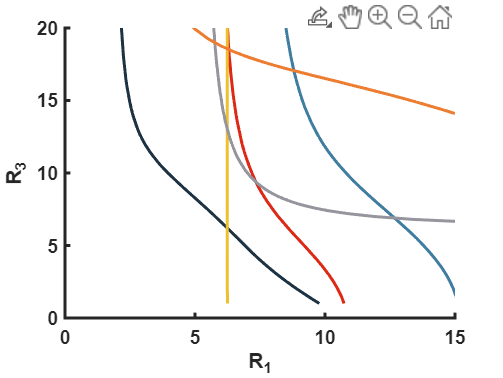


plot(x6,y6,'color',[237, 125, 49]/256, ...
    'LineWidth',1.5)


hold off

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');




%cont(rA,rB,R1,R3,uA3,uB3)

%cont(rA,rB,R1,R3,uA3,uB3)
%可能会有其他的椭球重叠

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

